This live-script runs solvers for the 1D acoustics equations via staggered grid FD methods.

In particular, the output pressure field is only stored at a single point in space.


% Demo: multipole sources in the staggered 1D acoustic solver
clear
close all
clc

% Setting computational space grids
dom_x = [0,1];
Nx = 401;
pressureGrid = GridSpace1D( Grid1DUnifPrimal(dom_x,Nx) );
velocityGrid = GridSpace1D( Grid1DUnifDual(pressureGrid.x) );

% Setting medium
medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);

% Setting computational time grid
dom_t = [0,1];
[~,~,~,cMax] = sampleMedium1D(pressureGrid,medium);
CFL = 0.9;
dt = CFL*(6/7)*pressureGrid.h/cMax;
Nt = ceil(diff(dom_t)/dt)+1;
dt = diff(dom_t)/(Nt-1); %recomputing dt to ensure time length is divisible by dt
times = dom_t(1):dt:dom_t(2);

% Output locations and times
x_rcv = 0.3;
outputGrid = GridSpace1D( Grid1D(dom_x,x_rcv) );
outputTimes = linspace(dom_t(1),dom_t(2),81);

% Defining MPS
xc = 0.7;
tc = 0.2;
fpeak = 10;
monopole = MultipoleTerm1D(xc,0,...
    @(t) RickerWave(t,tc,fpeak),...
    TargetField="pressure");

mps = MultipoleSource1D(monopole,ApproximationOrder=4);
source = mps.discretize(pressureGrid,velocityGrid);
% Initializing PML
pml = PML1D( ...
    WidthLeft=0.2, ...
    WidthRight=0.2, ...
    ReflectionCoefficient=1e-6, ...
    PolynomialDegree=3);

% Initialize solver
solver = AcousticSolver1D_PML( ...
    pressureGrid,times, ...
    outputGrid,outputTimes, ...
    medium, pml, ...
    SpatialOrder=4);

% Initial conditions
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));


% Run solver
[P,V] = solver.solve(p0,v0,Source=source);

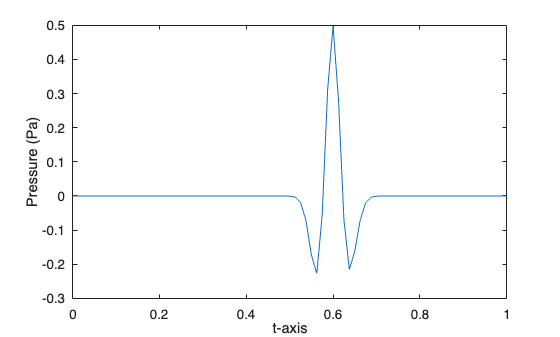

% Plotting results
figure
plot(outputTimes,P.values)
xlabel("t-axis")
ylabel(P.label+" ("+P.units+")")

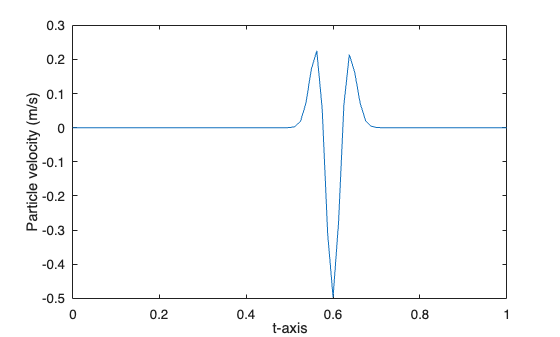


figure
plot(outputTimes,V.values)
xlabel("t-axis")
ylabel(V.label+" ("+V.units+")")